# Examen Parcial II

e = 1.60217656535e-19;% [A*s] Carga electrica de un electron

## Q01 En el amplificador óptico de Raman, ¿por qué motivo principal se debe colocar la fuente de bombeo en la salida de la fibra?.

## Q02 ¿Cuál ecuación describe el decremento en al densidad de portadores en un SOA con modelo adiabático?

## Q03 Un fotodetector APD tiene una respuesta cuyo valor es igual a la que tiene un fotodetector PIN equivalente en la misma banda óptica. Se supone que la respuesta no depende de la magnificación, y que ambos fotodetectores tienen la misma densidad de corriente equivalente de ruido térmico N_th. La potencia óptica que se entrega en ambos casos es igual y la potencia de ruido shot en el PIN es igual a la potencia de ruido térmico.

## En esas circumstancias, ¿Cuál ecuación describe el ratio ${\textrm{SNR}}_{\textrm{APD}} /{\textrm{SNR}}_{\textrm{PIN}}$?

Sabemos que la relación señal-ruido de un receptor viene dada por la ecuación $\frac{S}{N}=\frac{i^2 }{{\left(\Delta i_n \right)}^2 }$. Donde el denominador representa la suma de todo el ruido presente. Si sustituímos esta ecuación en el ratio que piden, tenemos


$$\frac{{\textrm{SNR}}_{\textrm{APD}} }{{\textrm{SNR}}_{\textrm{PIN}} }=\frac{{\frac{i^2 }{{\left(\Delta i_n \right)}^2 }}_{\textrm{APD}} }{{\frac{i^2 }{{\left(\Delta i_n \right)}^2 }}_{\textrm{PIN}} }=\frac{{\frac{M^2 \Re^2 P^2 }{{\left(\Delta i_n \right)}^2 }}_{\textrm{APD}} }{{\frac{\Re^2 P^2 }{{\left(\Delta i_n \right)}^2 }}_{\textrm{PIN}} }$$


Como nos dicen que tanto la respuesta como la pontencia óptica entregada es igual y asumiendo que el ruido presente es igual a la suma del ruido Shot más el ruido térmico, siendo para cada caso que ${\Delta i_n }^2 ={i_{\textrm{th}} }^2 +{i_{\textrm{sh}} }^2$ 


$$\frac{{\frac{M^2 \Re^2 P^2 }{{\left(\Delta i_n \right)}^2 }}_{\textrm{APD}} }{{\frac{\Re^2 P^2 }{{\left(\Delta i_n \right)}^2 }}_{\textrm{PIN}} }=\frac{{\frac{M^2 }{{\left(\Delta i_n \right)}^2 }}_{\textrm{APD}} }{{\frac{1}{{\left(\Delta i_n \right)}^2 }}_{\textrm{PIN}} }=\frac{{\frac{M^2 }{{i_{\textrm{th}} }^2 +{i_{\textrm{sh}} }^2 }}_{\textrm{APD}} }{{\frac{1}{{i_{\textrm{th}} }^2 +{i_{\textrm{sh}} }^2 }}_{\textrm{PIN}} }$$


Luego,  para el diodo PIN, el problema indica que ${i_{\textrm{th}} }^2 ={i_{\textrm{sh}} }^2$, por lo que es conveniente dividir numerador y denominador por ${i_{\textrm{th}} }^2$ que, siendo igual a ${N_{\textrm{th}} }^2 \Delta f$, es igual para ambos detectores.


$$\frac{{\frac{M^2 }{1+\frac{{{i_{\mathrm{sh}} }^2 }_{\mathrm{APD}} }{i_{\mathrm{th}}^2 }}}_{\mathrm{APD}} }{{\frac{1}{1+1}}_{\mathrm{PIN}} }=\frac{{2M}^2 }{1+\frac{{{i_{\mathrm{sh}} }^2 }_{\mathrm{APD}} }{{i_{\mathrm{th}} }^2 }}=\frac{{2M}^2 }{1+\frac{{{i_{\mathrm{sh}} }^2 }_{\mathrm{APD}} }{{{i_{\mathrm{sh}} }^2 }_{\mathrm{PIN}} }}$$


Por último, como ${{i_{\textrm{sh}} }^2 }_{\textrm{APD}} =2e\;M^2 F\left(M\right)\left(I_s +I_d \right)\Delta f$ y ${{i_{\textrm{sh}} }^2 }_{\textrm{PIN}} =2e\;\left(I_s +I_d \right)\Delta f$


$$\frac{{2M}^2 }{1+\frac{{{i_{\textrm{sh}} }^2 }_{\textrm{APD}} }{{{i_{\textrm{sh}} }^2 }_{\textrm{PIN}} }}=\frac{{2M}^2 }{1+\frac{2e\;M^2 F\left(M\right)\left(I_s +I_d \right)\Delta f}{2e\;\left(I_s +I_d \right)\Delta f}}=\frac{{2M}^2 }{1+M^2 F\left(M\right)}=\frac{2}{\frac{1}{M^2 }+F\left(M\right)}$$


## Q04 La corriente detectada por un detector PIN es u_1 uA en 1 Ohm cuando se transmite un bit uno y u_0 uA cuando es bit cero. La densidad espectral de potencia de ruido térmico es Sth W/Hz en 1 Ohm. Si el ruido shot es despreciable y el ancho de banda equivalente de ruido es B_e GHz, ¿Cuál es el valor de Q?

I1 = 10e-6; % [A] Corriente detectada por un detector PIN en 1 Ohm para bit 1
I0 = 1e-6; % [A] Corriente detectada por un detector PIN en 1 Ohm para bit 0
N_th = 100e-24; % [W/Hz] Densidad espectral de potencia de ruido térmico en 1 Ohm
B_e = 10e9; % [Hz] Ancho de banda equivalente de ruido

 Nos piden q en


$$P_e =\frac{1}{2}\textrm{erfc}\left(\frac{q}{\sqrt{2}}\right)$$


donde $q=\frac{v_{\max } -v_{\min } }{\sigma_{\min } +\sigma_{\max } }$.

Para calcular el valor medio de 1 y de 0 ($v_{\max } y\;v_{\min }$), podemos utilizar la corriente a 1 Ohm.

Para un fotodiodo PIN, el valor medio se puede calcular a través de $v_i =i^2$.

v_max = I1;
v_min = I0;

Del mismo modo para la desviación tipica, tenemos que de la definición de sensibilidad de receptores ópticos surge una relación entre la desviación, la densidad espectral de ruido equivalente y el ancho de banda, $\sigma_i =\sqrt{N_{\textrm{th}}^2 \textrm{Bw}+2e{\;v}_i \;\textrm{Bw}}$, pero nos dicen que el ruido shot es despreciable $2e{\;v}_i \;\textrm{Bw}=0$. Asimismo, la densidad de potencia de ruido se da en W/Hz, por lo que no es necesario elevar N_th al cuadrado.

sigma_max = sqrt(N_th * B_e);
sigma_min = sqrt(N_th * B_e);
q = (v_max - v_min) / (sigma_max + sigma_min)

q = 4.5000

## Q05 Si se define la relación de extinción como r_e = P_0 / P_1 se puede calcular la OMA a partir de la potencia promedia emitida mediante:

De la Wikipedia:

OMA es la diferencia entre dos niveles de potencia óptica de una señal digital generada por una fuente óptica. Viene dada por $\textrm{OMA}=P_1 -P_0$ (OJO: diferente a como se define en el problema) donde $P_1$es el nivel de potencia óptica generada cuando la fuente de luz está "encendida", y $P_0$es el nivel de potencia óptica cuando la fuente está "apagada".

El OMA se puede relacionar con la potencia promedia $P_{\textrm{av}} =\frac{\left(P_1 +P_0 \right)}{2}$ y la relación de extinción $r_e =\frac{P_1 }{P_0 }$(OJO: diferente a como se define en el problema) a través de


$$\mathrm{OMA}=2P_{\mathrm{av}} \frac{r_e -1}{r_e +1}=2P_{\mathrm{av}} \frac{\frac{P_1 }{P_0 }-1}{\frac{P_1 }{P_0 }+1}$$


Ahora, para el ejercicio $r_e =\frac{P_0 }{P_1 }$ por lo que multiplicamos numerador y denominador por esta definición y tenemos


$$\mathrm{OMA}\;=\;2P_{\mathrm{av}} \frac{\left(\frac{P_1 }{P_0 }-1\right)\frac{P_0 }{P_1 }}{\left(\frac{P_1 }{P_0 }+1\right)\frac{P_0 }{P_1 }}=2P_{\mathrm{av}} \frac{1-\frac{P_0 }{P_1 }}{1+\frac{P_0 }{P_1 }}=2P_{\mathrm{av}} \frac{1-r_e }{1+r_e }$$


## Q06 Se entrega una señal óptica coherente ideal de potencia Po [dBm] a un detector APD de respuesta R [A/W] y magnificación M. La potencia eléctrica generada en 1 Ohm es:

Po = -20; % [dBm] Potencia de señal
R = 0.8; % [A/W] Respuesta del detector APD
M = 20; % Factor de magnificación
i = 10*log10((20*0.8*10^((-20-30)/10))^2) + 30 % [dBm] Potencia eléctrica generada

i = -45.9176

## Q07 ¿Cuál ecuación es la que corresponde con la probabilidad de error de detectar un 0 cuando se transmite un 1?

Si denominamos $p\left(v\right)$a la función de densidad de probabilidad de la tensión de salida del receptor, $p\left(v\right)\mathrm{dv}$ es la probabilidad de que dicha tensión de salida tenga un valor comprendido entre $v$ y $v+d\;v$. La función tendrá forma gaussiana pero será diferente según el bit transmitido sea 0 o 1.


$$p_i \left(v\right)=\frac{1}{\sqrt{2\pi \sigma_i }}\mathrm{exp}\left\lbrack -\frac{{\left(v-v_i \right)}^2 }{2{\sigma_i }^2 }\right\rbrack$$


donde el subindice $i$ toma los valores "max" o "min".

Luego, $P\left(1/0\right)$ es la probabilidad de que, habiéndose enviado un 0, $v$ resulte ser mayor que el umbral establecido, $v_u$. Igualmente para $P\left(0/1\right)$.

$P\left(1/0\right)$ = $\int_{v_u }^{\infty } p_{\mathrm{min}} \left(v\right)\mathrm{dv}$ 

y

 $P\left(0/1\right)$ = $\int_{-\infty }^{v_u } p_{\mathrm{max}} \left(v\right)\mathrm{dv}$

Se pide $P\left(0/1\right)$, para $p_{\mathrm{max}} \left(v\right)$ gaussiano es

 
$$P\left(0/1\right)=\int_{-\infty }^{v_u } \frac{1}{\sqrt{2\pi }\sigma_1 }e^{-\;\frac{{\left(v-v_1 \right)}^2 }{2{\sigma_1 }^2 }} \mathrm{dv}$$


## Q09 Considerando el siguiente gráfico, de la respuesta de modulación de pequeña señal de un diodo láser polarizado por encima de umbral, ¿A qué corresponde $\alpha =\Gamma_R \;\left(\mathrm{siendo}\;\Omega_R =w_o \right)$?

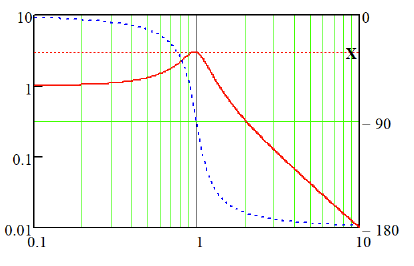

En la figura se muestra el módulo de la respuesta de modulación de un diodo láser. La X marca el punto donde $w={w_0 =\;\Omega }_R$, que es la resonancia interna que el dispositivo posee a la frecuencia de las oscilaciones de relajación. El valor de la función de transferencia en dicho pico puede calcularse como $X=\Delta S\left(\Omega_R \right)/\Delta S\left(0\right)\approx \Omega_R /2\Gamma_R$(pag. 292 del libro de Capmany) o $X=\frac{w_0 }{2\alpha }$ en la nomeclatura del problema. Por lo tanto, $\alpha =\frac{w_0 }{2X}$.

## Q13 Considerando un enlace óptico sin dispersión, con detector PIN dominado por ruido térmico (ruido shot despreciable), con atenuación A (dB/km), con potencia emisora promedia P_av y relación de extinción cero, ¿cuál de las siguientes opciones es la que corresponde a la longitud aproximada del enlace L (Km) para un determinado valor de Q?

El parámetro Q viene dado por $\frac{v_1 -v_0 }{\sigma_1 +\sigma_0 }$, donde $v_i ={R\;P}_i$ y ${\sigma_i }^2 ={i_n }^2$.

Por un lado, la relación de extinción es cero asi que $P_{\mathrm{av}} =\frac{P_1 }{2}$ por lo que, añadiendo la atenación, $v_1 ={R\;\frac{2{\mathrm{P}}_{\mathrm{av}} }{P_A }}$y $v_0 =0$. Aquí $P_A ={10}^{\frac{A*L}{10}}$que es de donde sacaremos la longitud.

Por otro lado, el ruido shot es despreciable así que ${i_n }^2 ={{i_{\mathrm{th}} }^2 =N_{\mathrm{th}} }^2 B_e \to \sigma_1 =N_{\mathrm{th}} \sqrt{B_e }$.

Volviendo a Q, se tiene que


$$Q=\frac{v_1 }{\sigma_1 +\sigma_2 }=\frac{2R\;P_{\mathrm{av}} }{2N_{\mathrm{th}} \sqrt{B_e }P_A }$$


Despejando L en $P_A$


$$P_A ={10}^{\frac{A*L}{10}} =\frac{2R\;P_{\mathrm{av}} }{2N_{\mathrm{th}} \sqrt{B_e }Q}\to L={10\;\mathrm{log}}_{10} \left(\frac{R\;P_{\mathrm{av}} }{Q\;N_{\mathrm{th}} \sqrt{B_e }}\right)/A$$


## Q14 El diagram de ojo a la salida de un enlace óptico tiene las siguientes características en el simulador VPI: ¿Cuál es el valor de Q?

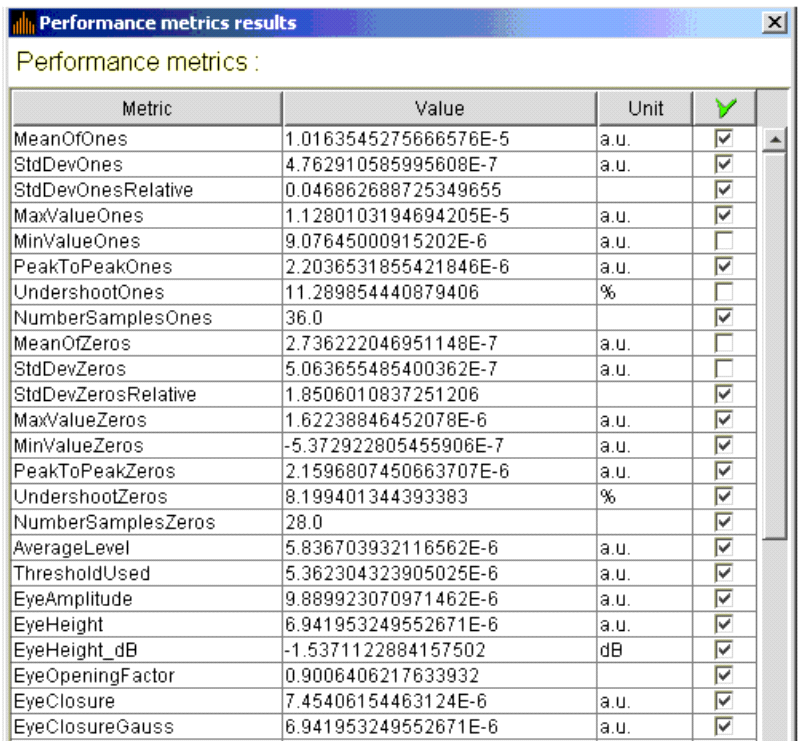 

(1.016354527e-5-2.736222045e-7) / (4.7629105e-7+5.06365548e-7)

ans = 10.0645

## Q16 ¿Cuál es la ecuación de frecuencia de relajación de un diodo láser?

Dadas las 2 ecuaciones de emisión del láser en regimen transitorio para el número de fotones y de electrónes:


$$\frac{d\left(\Delta N\right)}{\mathrm{dt}}=-\Delta N\Gamma_N -\Delta S\left(G+G_S S\right)$$



$$\frac{d\left(\Delta S\right)}{\mathrm{dt}}=-\Delta S\Gamma_S +\Delta N\left(G_N S+{n_{\mathrm{sp}} G}_N \right)$$


Donde los coeficientes $\Gamma_S \;$y $\Gamma_N \;$representan las tasas de decaimiento del número de electrones y fotones y $G_S =-\frac{\varepsilon_{\mathrm{NL}} }{t_{\mathrm{ph}} }$. 

Para este sistema de ecuaciones diferenciales se tienen como solución dos funciones de tipo exponencial que representan una solución oscilatoria amortiguada ([oscilaciones de relajación](https://en.wikipedia.org/wiki/Relaxation_(physics))),


$$\Delta N\left(t\right)={\Delta N_0 } e^{-\mathrm{qt}}$$



$$\Delta S\left(t\right)={\Delta S_0 } e^{-\mathrm{qt}}$$


donde $q=\Gamma_R \pm j\Omega_R \ldotp$

En $q$, $\Omega_R$es la frecuencia angular de dichas oscilaciones y en la práctica se puede aproximar por $\Omega_R \approx \sqrt{{G\;G}_N S}=\sqrt{\frac{\eta_i G_N \left(I-I_{\mathrm{th}} \right)}{e}}=\sqrt{\frac{\eta_i \Gamma v_g \sigma_g \left(I-I_{\mathrm{th}} \right)}{{e\;V}_{\mathrm{act}} }}$

## Q19 El ruido eléctrico de un detector PIN se presenta en la figura en función de la potencia óptica entregada. ¿A que corresponde la potencia óptica P_2 en [W]?

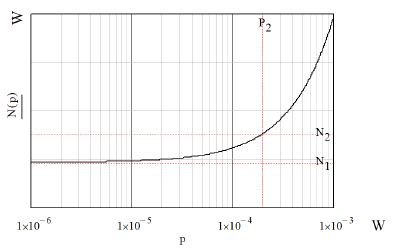

$N_1 ={N_{\mathrm{th}} }^2 \mathrm{Be}$ (No hay Potencia óptica entregada)


$$N_2 ={N_{\mathrm{th}} }^2 \mathrm{Be}+2e\;R\;P_2 \mathrm{Be}$$



$$N_2 -N_1 =2e\;R\;P_2 \mathrm{Be}\to P_2 =\frac{\left.{\left(N\right.}_2 -N_1 \right)}{2e\;R\;\mathrm{Be}}$$


## Q20 Un láser tiene un nivel de ruido de intensidad relativo RIN [dBc/Hz] y emite una potencia de Po dBm a la frecuencia de nu THz. 

## Se conecta un filtro óptico de ancho de banda Bo GHz y atenuación L dB entre la salida del láser y la entrada de un detector PIN con respuesta R [A/W]. El ancho de banda eléctrica equivalente del detector es Be GHz.

## La potencia (dBm en 1Ω) de ruido batido señal-ASE detecta por un analizador de espectro eléctrico configurado con un ancho de banda de resolución de RBW MHz es:

RIN = -130; 
Po = 5; 
nu = 193.1; 
Bo = 320;
L = 10; 
R = 0.8; 
Be = 20; 
RBW = 40;